# Clipping and Hidden Surface Determination Examples

[Link to lecture notes](https://jonshiach.github.io/graphics-book/files/4.0_Clipping_and_HSD.html)

### Example 33

Use the Cyrus-Beck algorithm to clip the lines $\mathbf{a} \to \mathbf{b}$, $\mathbf{c} \to \mathbf{d}$, $\mathbf{e} \to \mathbf{f}$ and $\mathbf{g} \to \mathbf{h}$ in the diagram below.

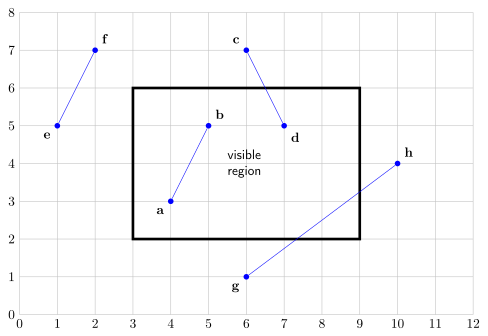

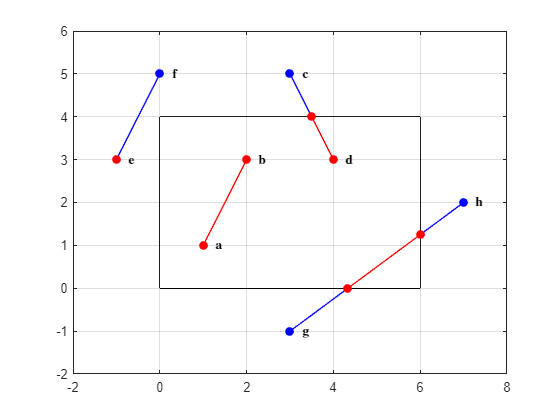

clear

% Define point co-ordinates
V = [ 1,  2,  3,  4, -1,  0,  3,  7 ;
      1,  3,  5,  3,  3,  5, -1,  2 ];
labels = ["a", "b", "c", "d", "e", "f", "g", "h"];

% Define edge normals and points
n = [ 0, -1,  0,  1 ;
      1,  0, -1,  0 ];
p = [ 0,  6,  6,  0 ;
      0,  0,  4,  4 ];

% Loop through lines
Vclip = V;
for i = 1 : 4
    a = 2 * i - 1;
    b = 2 * i;

    % Loop through edges and apply Cyrus-Beck algorithm
    for j = 1 : 4
        [Vclip(:,a), Vclip(:,b)] = cyrus_beck(Vclip(:,a), Vclip(:,b), p(:,j), n(:,j));
    end
end

% Plot lines
figure
plot([p(1,:), p(1,1)], [p(2,:), p(2,1)], 'k')
hold on
for i = 1 : 4
    plot(V(1,2*i-1:2*i), V(2,2*i-1:2*i), 'b-o', MarkerFaceColor='b')
    plot(Vclip(1,2*i-1:2*i), Vclip(2,2*i-1:2*i), 'r-o', MarkerFaceColor='r')
    text(V(1,2*i-1)+0.25, V(2,2*i-1), sprintf('$\\mathbf{%s}$', labels(2*i-1)), Interpreter='latex')
    text(V(1,2*i)+0.25, V(2,2*i), sprintf('$\\mathbf{%s}$', labels(2*i)), Interpreter='latex')
end
hold off
axis([-2, 8, -2, 6])
grid on

### Clip screen space

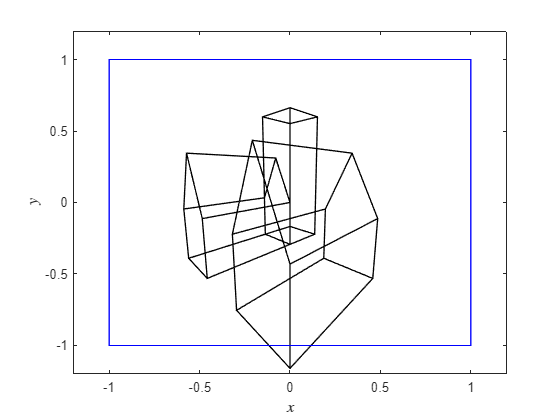

clear

% Load screen space coordinates
load('screen_space_coords.mat');

% Define frustrum cube
Vcube = [ -1,  1,  1, -1, -1,  1,  1, -1 ;
          -1, -1,  1,  1, -1, -1,  1,  1 ;
          -1, -1, -1, -1,  1,  1,  1,  1 ];
Fcube = [ 1, 4, 3, 2 ;
          1, 2, 6, 5 ; 
          2, 3, 7, 6 ;
          3, 4, 8, 7 ;
          4, 1, 5, 8 ;
          5, 6, 7, 8 ];

% Plot screen space (from viewing position)
figure()
h1 = axes;
patch('Vertices', Vscreen([1,3,2],:)', 'Faces', Fworld, FaceColor='w', FaceAlpha=0, LineWidth=1)
patch('Vertices', Vcube', 'Faces', Fcube, FaceAlpha=0, EdgeColor="blue")

xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 12)
ylabel('$z$', 'Interpreter', 'latex', 'FontSize', 12)
zlabel('$y$', 'Interpreter', 'latex', 'FontSize', 12)
set(h1, 'Ydir', 'reverse')
view(0,0)
axis([-1.2, 1.2, -1.2, 1.2, -1.2, 1.2])
box on

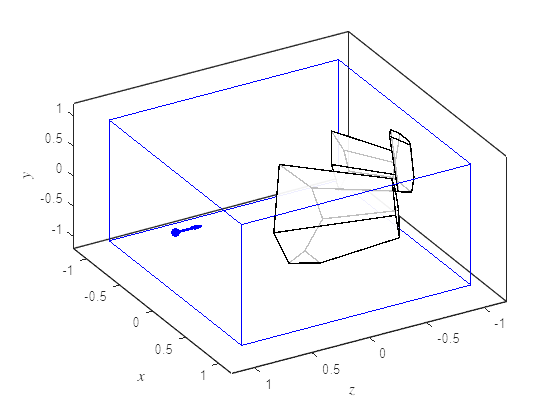

% Clip screen space co-ordinates
[Vclip, Fclip] = clipped_space(Vscreen, Fworld);

% Plot clipped space viewed from the side
figure()
h1 = axes;
patch('Vertices', Vclip([1,3,2],:)', 'Faces', Fclip, FaceColor='w', FaceAlpha=0.75, LineWidth=1)
patch('Vertices', Vcube', 'Faces', Fcube, FaceAlpha=0, EdgeColor="blue")
hold on
plot3(0,1,0,'bo',MarkerFaceColor='b')
quiver3(0,1,0,0,-0.25,0, 'b', LineWidth=2, MaxHeadSize=1)
hold off

xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 12)
ylabel('$z$', 'Interpreter', 'latex', 'FontSize', 12)
zlabel('$y$', 'Interpreter', 'latex', 'FontSize', 12)
set(h1, 'Ydir', 'reverse')
view(60,45)
axis([-1.2, 1.2, -1.2, 1.2, -1.2, 1.2])
box on

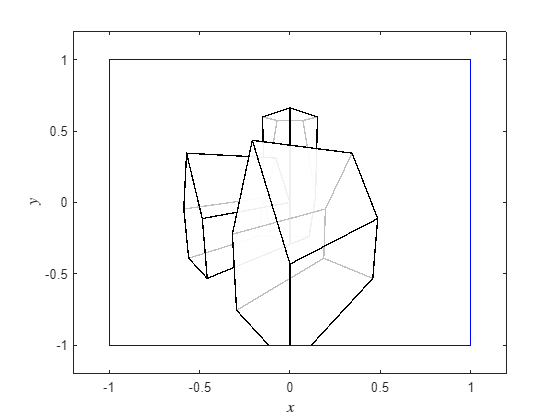

% Plot clipped space viewed looking down the z-axis.
figure()
h1 = axes;
patch('Vertices', Vclip([1,3,2],:)', 'Faces', Fclip, FaceColor='w', FaceAlpha=0.75, LineWidth=1)
patch('Vertices', Vcube(1:3,:)', 'Faces', Fcube, FaceAlpha=0, EdgeColor="blue")

xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 12)
ylabel('$z$', 'Interpreter', 'latex', 'FontSize', 12)
zlabel('$y$', 'Interpreter', 'latex', 'FontSize', 12)
set(h1, 'Ydir', 'reverse')
view(0,0)
axis([-1.2, 1.2, -1.2, 1.2, -1.2, 1.2])
box on
view(0,0)

### Example 35

A tetrahedron object is defined by the following homogeneous screen space co-ordinates and face matrix


$$V = \pmatrix{1 & 3 & 2 & 2 \cr 2 & 2 & 2 & 4 \cr -6 & -5 & -3 & -5 \cr 1 & 1 & 1 & 1 }, \qquad
F = \pmatrix{ 1 & 3 & 2 \cr 1 & 2 & 4 \cr 2 & 3 & 4 \cr 1 & 4 & 3}.$$


The object is viewed looking down the $z$-axis from the viewing position at (0,0,1). Determine which of the faces of the object are front facing.

% Define vertices, faces and viewing point
V = [  1,  3,  2,  2 ; 
       2,  2,  2,  4 ;
      -6, -5, -3, -5 ;
       1,  1,  1,  1 ];
F = [ 1, 3, 2 ;
      1, 2, 4 ;
      2, 3, 4 ;
      1, 4, 3 ];
p = [0 ; 0 ; 1];

% Loop through faces
for i = 1 : 4
    fprintf('------------\nFace %1i:', i)
    n = sym(cross(V(1:3,F(i,2)) - V(1:3,F(i,1)), V(1:3,F(i,3)) - V(1:3,F(i,2))))
    ndotv = sym(dot(n, V(1:3,F(i,1)) - p))
    if ndotv < 0
        disp('front facing')
    else
        disp('back facing')
    end
end

------------
Face 1:

$$n = \left(\begin{array}{c} 0\\ 5\\ 0 \end{array}\right)$$

$$ndotv = 10$$

back facing


------------
Face 2:

$$n = \left(\begin{array}{c} -2\\ -1\\ 4 \end{array}\right)$$

$$ndotv = -32$$

front facing


------------
Face 3:

$$n = \left(\begin{array}{c} -4\\ -2\\ -2 \end{array}\right)$$

$$ndotv = -4$$

front facing


------------
Face 4:

$$n = \left(\begin{array}{c} 6\\ -2\\ -2 \end{array}\right)$$

$$ndotv = 16$$

back facing


### Applying backface culling to the clip space

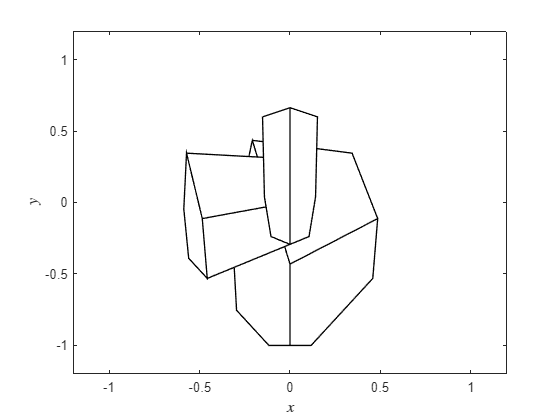

% Apply backface culling
Ffront = backface_culling(Vclip, Fclip, [0 ; 0 ; 1]);

% Plot front facing polygons space (from viewing position)
figure
hold on
for i = 1 : size(Ffront, 1)
    x = zeros(1, size(Ffront,2));
    y = zeros(1, size(Ffront,2));
    for j = 1 : size(Ffront, 2)
        x(j) = Vclip(1,Ffront(i,j));
        y(j) = Vclip(2,Ffront(i,j));
    end
    fill(x, y, 'w', LineWidth=1)
end

xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 12)
ylabel('$y$', 'Interpreter', 'latex', 'FontSize', 12)
axis([-1.2, 1.2, -1.2, 1.2, -1.2, 1.2])
box on

### Applying painter's algorithm to the front facing polygons

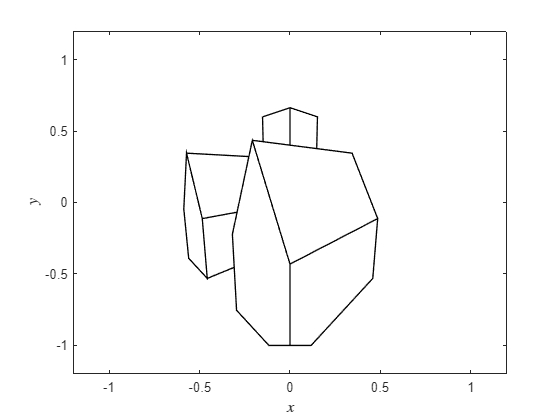

% Apply painters algorithm to the front facing polygons
Fpainter = painters(Vclip, Ffront);

% Plot front facing polygons in order of z distance
figure
hold on
for i = 1 : size(Ffront, 1)
    x = zeros(1, size(Fpainter,2));
    y = zeros(1, size(Fpainter,2));
    for j = 1 : size(Ffront, 2)
        x(j) = Vclip(1,Fpainter(i,j));
        y(j) = Vclip(2,Fpainter(i,j));
    end
    fill(x, y, 'w', LineWidth=1)
end

xlabel('$x$', 'Interpreter', 'latex', 'FontSize', 12)
ylabel('$y$', 'Interpreter', 'latex', 'FontSize', 12)
axis([-1.2, 1.2, -1.2, 1.2, -1.2, 1.2])
box on

## Functions

### Cyrus-Beck algorithm

function [a, b] = cyrus_beck(a, b, p, n)

da = dot(a - p, n);
db = dot(b - p, n);
t = da / (da - db);
if da < 0 && db > 0
    a = a + t * (b - a);
elseif da > 0 && db < 0
    b = a + t * (b - a);
elseif da < 0 && db < 0
    b = a;
end

end

### Sutherland-Hodgman algorithm

function [Vclip, Fclip] = clipped_space(V, F)

% Define cube region points and normal vectors
P = [ -1, -1,  1,  1, -1,  1 ; 
      -1, -1,  1,  1, -1,  1 ; 
       1,  1, -1, -1,  1, -1 ];
n = [  0,  0, -1,  0,  1,  0 ;  
       1,  0,  0,  0,  0, -1 ; 
       0, -1,  0,  1,  0,  0 ];

% Loop through the polygons in F
Vclip = V;   
Fclip = [];
for poly = 1 : size(F, 1)

    % Loop through the edges of the clipping cube
    output = F(poly, :);
    for edge = 1 : size(P,2)
        input = output;
        output = [];
        prev = input(end);

        for i = 1 : length(input)
            curr = input(i);
            dcurr = dot(Vclip(1:3,curr) - P(:,edge), n(:,edge));
            dprev = dot(Vclip(1:3,prev) - P(:,edge), n(:,edge));

            % Check if polygon edge crosses clipping cube edge
            if dcurr > 0 
                % Current point is inside
                if dprev < 0
                     % Previous point is outside so add intersection to output list
                    t = dprev / (dprev - dcurr);
                    int = [Vclip(1:3,prev) + t * (Vclip(1:3,curr) - Vclip(1:3,prev)) ; 1];
                    Vclip = [Vclip, int];
                    output = [output, size(Vclip, 2)];
                end

                % Add current point to output list
                output = [output, curr];

            elseif dprev > 0
                % Current point is outside so add intersection to output list
                t = dprev / (dprev - dcurr);
                int = [Vclip(1:3,prev) + t * (Vclip(1:3,curr) - Vclip(1:3,prev)) ; 1];
                Vclip = [Vclip, int];
                output = [output, size(Vclip, 2)];
            end

            % Update previous
            prev = curr;
        end
    end

    % If outputlist is non-empty add to Fclipped
    if ~isempty(output)
        if isempty(Fclip)
            Fclip = output;
            continue
        end

        diff = length(output) - size(Fclip,2);
        if diff > 0
            % Pad out Fclip
            Fclip = [Fclip, repmat(Fclip(:,end), 1, diff)];
        elseif diff < 0
            % Pad out outputlist
            output = [output, repmat(output(end), 1, -diff)];
        end

        % Add outputlist to Fclipped
        Fclip = [Fclip ; output];
    end
end

end

### Backface culling

function Ffront = backface_culling(V, F, p)

Ffront = [];
for i = 1 : size(F, 1)
    n = cross(V(1:3,F(i,2)) - V(1:3,F(i,1)), V(1:3,F(i,3)) - V(1:3,F(i,2)));
    if dot(n, V(1:3,F(i,1)) - p) < 0
        Ffront = [Ffront ; F(i,:)];
    end
end

end

### Painter's algorithm

function Fpainter = painters(V, F)

distance = -1 * ones(size(F, 1), 1);
for i = 1 : size(F, 1)
    for j = 1 : size(F, 2)
        distance(i) = max(distance(i), V(3,F(i,j)));
    end
end

[~, idx] = sort(distance);
Fpainter = F(idx, :);

end